- Изобразить циферблат часов с движущимися стрелками

clear
clc
close all
figure('name', 'Clock');
plot(11.5*cosd(0:360), 11.5*sind(0:360), 'b', 'LineWidth', 6); 
hold on

fill(-11*cosd(0:360), 11*sind(0:360), [0.9 0.9 0.9]);
fill(0.5*cosd(0:360), 0.5*sind(0:360), 'b')

for n=1:12
    text(-9*cosd(90+n*360/12), 9*sind(90+n*360/12),num2str(n), 'FontSize', 12)
    plot([10 11].*cosd(90+n*360/12), [10 11].*sind(90+n*360/12), 'k', 'LineWidth', 2)
    for nn=1:4
        plot([10.5 11].*cosd(90+n*360/12+nn*6), [10.5 11].*sind(90+n*360/12+nn*6), 'k')
    end
end

s=[]; m=[]; h=[]


h =

     []



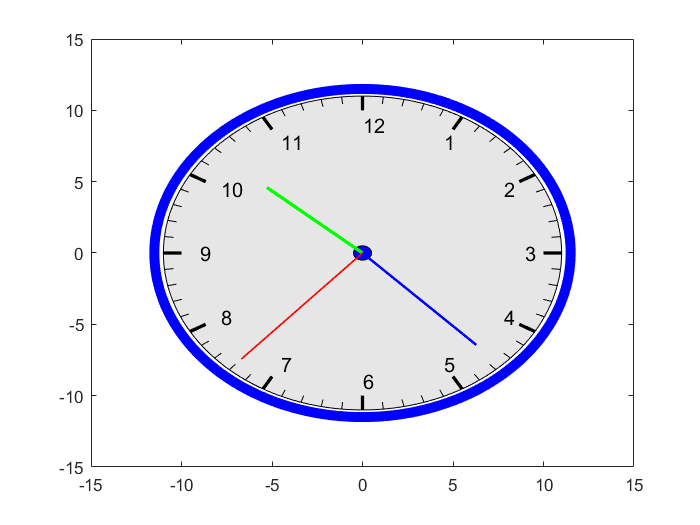

while(true)
    time=fix(clock);
    hs=90+time(6)*6;
    hm=90+time(5)*6+time(6)/10;
    hh=90+time(4)*30+time(5)/2;
    
    delete(h);
    delete(m);
    delete(s);
    h=plot([0 -7*cosd(hh)],[0 7*sind(hh)], 'g', 'LineWidth', 2);
    m=plot([0 -9*cosd(hm)],[0 9*sind(hm)], 'b', 'LineWidth', 1.5);
    s=plot([0 -10*cosd(hs)],[0 10*sind(hs)], 'r', 'LineWidth', 1);
    pause(1)
end